load"C:\Users\anand\OneDrive\Desktop\Dissertation\prog\workspace  allll.mat"

path = "C:\Users\anand\OneDrive\Desktop\Deep_learning\train"

path = "C:\Users\anand\OneDrive\Desktop\Deep_learning\train"

data = imageDatastore(path,"IncludeSubfolders",true,"LabelSource","foldernames")

data =   ImageDatastore with properties:

                       Files: {
                              ' ...\anand\OneDrive\Desktop\Deep_learning\train\baboon\n02486410_0.JPEG';
                              ' ...\anand\OneDrive\Desktop\Deep_learning\train\baboon\n02486410_1.JPEG';
                              ' ...\anand\OneDrive\Desktop\Deep_learning\train\baboon\n02486410_10.JPEG'
                               ... and 2197 more
                              }
                     Folders: {
                              'C:\Users\anand\OneDrive\Desktop\Deep_learning\train'
                              }
                      Labels: [baboon; baboon; baboon ... and 2197 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn:

data_agumented = augmentedImageDatastore([224 224 3],data,"ColorPreprocessing","gray2rgb")

data_agumented =   augmentedImageDatastore with properties:

             NumObservations: 2200
                       Files: {2200×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'gray2rgb'
                  OutputSize: [224 224]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


numClasses = numel(categories(data.Labels));

[dataTrain,dataTest] = splitEachLabel(data,0.7 , "randomized")

dataTrain =   ImageDatastore with properties:

                       Files: {
                              ' ...\anand\OneDrive\Desktop\Deep_learning\train\baboon\n02486410_0.JPEG';
                              ' ...\anand\OneDrive\Desktop\Deep_learning\train\baboon\n02486410_1.JPEG';
                              ' ...\anand\OneDrive\Desktop\Deep_learning\train\baboon\n02486410_100.JPEG'
                               ... and 1537 more
                              }
                     Folders: {
                              'C:\Users\anand\OneDrive\Desktop\Deep_learning\train'
                              }
                      Labels: [baboon; baboon; baboon ... and 1537 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     Re

dataTest =   ImageDatastore with properties:

                       Files: {
                              ' ...\anand\OneDrive\Desktop\Deep_learning\train\baboon\n02486410_10.JPEG';
                              ' ...\anand\OneDrive\Desktop\Deep_learning\train\baboon\n02486410_102.JPEG';
                              ' ...\anand\OneDrive\Desktop\Deep_learning\train\baboon\n02486410_107.JPEG'
                               ... and 657 more
                              }
                     Folders: {
                              'C:\Users\anand\OneDrive\Desktop\Deep_learning\train'
                              }
                      Labels: [baboon; baboon; baboon ... and 657 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     Re

Trainset_1 = augmentedImageDatastore([224 224],dataTrain,"ColorPreprocessing","gray2rgb");
Testset_1 = augmentedImageDatastore([224 224],dataTest,"ColorPreprocessing","gray2rgb");


# Create Deep Learning Network Architecture

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `lgraph`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 25-Aug-2023 14:29:55

## Create Layer Graph

Create the layer graph variable to contain the network layers.

lgraph = layerGraph();

## Add Layer Branches

Add the branches of the network to the layer graph. Each branch is a linear array of layers.

tempLayers = [
    imageInputLayer([224 224 3],"Name","data")
    convolution2dLayer([7 7],64,"Name","conv1-7x7_s2","BiasLearnRateFactor",2,"Padding",[3 3 3 3],"Stride",[2 2])
    reluLayer("Name","conv1-relu_7x7")
    maxPooling2dLayer([3 3],"Name","pool1-3x3_s2","Padding",[0 1 0 1],"Stride",[2 2])
    crossChannelNormalizationLayer(5,"Name","pool1-norm1","K",1)
    convolution2dLayer([1 1],64,"Name","conv2-3x3_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","conv2-relu_3x3_reduce")
    convolution2dLayer([3 3],192,"Name","conv2-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","conv2-relu_3x3")
    crossChannelNormalizationLayer(5,"Name","conv2-norm2","K",1)
    maxPooling2dLayer([3 3],"Name","pool2-3x3_s2","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],64,"Name","inception_3a-1x1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],96,"Name","inception_3a-3x3_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_3x3_reduce")
    convolution2dLayer([3 3],128,"Name","inception_3a-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_3a-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],16,"Name","inception_3a-5x5_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_5x5_reduce")
    convolution2dLayer([5 5],32,"Name","inception_3a-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_3a-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_3a-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],32,"Name","inception_3a-pool_proj","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_3a-output");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_3b-1x1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_3b-3x3_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_3x3_reduce")
    convolution2dLayer([3 3],192,"Name","inception_3b-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_3b-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_3b-5x5_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_5x5_reduce")
    convolution2dLayer([5 5],96,"Name","inception_3b-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_3b-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_3b-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_3b-pool_proj","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_3b-output")
    maxPooling2dLayer([3 3],"Name","pool3-3x3_s2","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],192,"Name","inception_4a-1x1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],96,"Name","inception_4a-3x3_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_3x3_reduce")
    convolution2dLayer([3 3],208,"Name","inception_4a-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4a-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],16,"Name","inception_4a-5x5_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_5x5_reduce")
    convolution2dLayer([5 5],48,"Name","inception_4a-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4a-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4a-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4a-pool_proj","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4a-output");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_4b-1x1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],112,"Name","inception_4b-3x3_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_3x3_reduce")
    convolution2dLayer([3 3],224,"Name","inception_4b-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4b-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],24,"Name","inception_4b-5x5_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_5x5_reduce")
    convolution2dLayer([5 5],64,"Name","inception_4b-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4b-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4b-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4b-pool_proj","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4b-output");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_4c-1x1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_4c-3x3_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_3x3_reduce")
    convolution2dLayer([3 3],256,"Name","inception_4c-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4c-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],24,"Name","inception_4c-5x5_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_5x5_reduce")
    convolution2dLayer([5 5],64,"Name","inception_4c-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4c-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4c-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4c-pool_proj","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4c-output");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],112,"Name","inception_4d-1x1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],144,"Name","inception_4d-3x3_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_3x3_reduce")
    convolution2dLayer([3 3],288,"Name","inception_4d-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4d-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_4d-5x5_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_5x5_reduce")
    convolution2dLayer([5 5],64,"Name","inception_4d-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4d-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4d-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4d-pool_proj","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4d-output");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","inception_4e-1x1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_4e-3x3_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_3x3_reduce")
    convolution2dLayer([3 3],320,"Name","inception_4e-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4e-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_4e-5x5_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_5x5_reduce")
    convolution2dLayer([5 5],128,"Name","inception_4e-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4e-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4e-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_4e-pool_proj","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_4e-output")
    maxPooling2dLayer([3 3],"Name","pool4-3x3_s2","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","inception_5a-1x1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_5a-3x3_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_3x3_reduce")
    convolution2dLayer([3 3],320,"Name","inception_5a-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_5a-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_5a-5x5_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_5x5_reduce")
    convolution2dLayer([5 5],128,"Name","inception_5a-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_5a-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_5a-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_5a-pool_proj","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_5a-output");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],384,"Name","inception_5b-1x1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],192,"Name","inception_5b-3x3_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_3x3_reduce")
    convolution2dLayer([3 3],384,"Name","inception_5b-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_5b-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],48,"Name","inception_5b-5x5_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_5x5_reduce")
    convolution2dLayer([5 5],128,"Name","inception_5b-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_5b-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_5b-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_5b-pool_proj","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_5b-output")
    globalAveragePooling2dLayer("Name","pool5-7x7_s1")
    dropoutLayer(0.4,"Name","pool5-drop_7x7_s1")
    fullyConnectedLayer(5,"Name","fc")
    softmaxLayer("Name","prob")
    classificationLayer("Name","classoutput")];
lgraph = addLayers(lgraph,tempLayers);

% clean up helper variable
clear tempLayers;

## Connect Layer Branches

Connect all the branches of the network to create the network graph.

lgraph = connectLayers(lgraph,"pool2-3x3_s2","inception_3a-1x1");
lgraph = connectLayers(lgraph,"pool2-3x3_s2","inception_3a-3x3_reduce");
lgraph = connectLayers(lgraph,"pool2-3x3_s2","inception_3a-5x5_reduce");
lgraph = connectLayers(lgraph,"pool2-3x3_s2","inception_3a-pool");
lgraph = connectLayers(lgraph,"inception_3a-relu_1x1","inception_3a-output/in1");
lgraph = connectLayers(lgraph,"inception_3a-relu_3x3","inception_3a-output/in2");
lgraph = connectLayers(lgraph,"inception_3a-relu_5x5","inception_3a-output/in3");
lgraph = connectLayers(lgraph,"inception_3a-relu_pool_proj","inception_3a-output/in4");
lgraph = connectLayers(lgraph,"inception_3a-output","inception_3b-1x1");
lgraph = connectLayers(lgraph,"inception_3a-output","inception_3b-3x3_reduce");
lgraph = connectLayers(lgraph,"inception_3a-output","inception_3b-5x5_reduce");
lgraph = connectLayers(lgraph,"inception_3a-output","inception_3b-pool");
lgraph = connectLayers(lgraph,"inception_3b-relu_1x1","inception_3b-output/in1");
lgraph = connectLayers(lgraph,"inception_3b-relu_3x3","inception_3b-output/in2");
lgraph = connectLayers(lgraph,"inception_3b-relu_5x5","inception_3b-output/in3");
lgraph = connectLayers(lgraph,"inception_3b-relu_pool_proj","inception_3b-output/in4");
lgraph = connectLayers(lgraph,"pool3-3x3_s2","inception_4a-1x1");
lgraph = connectLayers(lgraph,"pool3-3x3_s2","inception_4a-3x3_reduce");
lgraph = connectLayers(lgraph,"pool3-3x3_s2","inception_4a-5x5_reduce");
lgraph = connectLayers(lgraph,"pool3-3x3_s2","inception_4a-pool");
lgraph = connectLayers(lgraph,"inception_4a-relu_1x1","inception_4a-output/in1");
lgraph = connectLayers(lgraph,"inception_4a-relu_3x3","inception_4a-output/in2");
lgraph = connectLayers(lgraph,"inception_4a-relu_5x5","inception_4a-output/in3");
lgraph = connectLayers(lgraph,"inception_4a-relu_pool_proj","inception_4a-output/in4");
lgraph = connectLayers(lgraph,"inception_4a-output","inception_4b-1x1");
lgraph = connectLayers(lgraph,"inception_4a-output","inception_4b-3x3_reduce");
lgraph = connectLayers(lgraph,"inception_4a-output","inception_4b-5x5_reduce");
lgraph = connectLayers(lgraph,"inception_4a-output","inception_4b-pool");
lgraph = connectLayers(lgraph,"inception_4b-relu_1x1","inception_4b-output/in1");
lgraph = connectLayers(lgraph,"inception_4b-relu_3x3","inception_4b-output/in2");
lgraph = connectLayers(lgraph,"inception_4b-relu_5x5","inception_4b-output/in3");
lgraph = connectLayers(lgraph,"inception_4b-relu_pool_proj","inception_4b-output/in4");
lgraph = connectLayers(lgraph,"inception_4b-output","inception_4c-1x1");
lgraph = connectLayers(lgraph,"inception_4b-output","inception_4c-3x3_reduce");
lgraph = connectLayers(lgraph,"inception_4b-output","inception_4c-5x5_reduce");
lgraph = connectLayers(lgraph,"inception_4b-output","inception_4c-pool");
lgraph = connectLayers(lgraph,"inception_4c-relu_1x1","inception_4c-output/in1");
lgraph = connectLayers(lgraph,"inception_4c-relu_3x3","inception_4c-output/in2");
lgraph = connectLayers(lgraph,"inception_4c-relu_5x5","inception_4c-output/in3");
lgraph = connectLayers(lgraph,"inception_4c-relu_pool_proj","inception_4c-output/in4");
lgraph = connectLayers(lgraph,"inception_4c-output","inception_4d-1x1");
lgraph = connectLayers(lgraph,"inception_4c-output","inception_4d-3x3_reduce");
lgraph = connectLayers(lgraph,"inception_4c-output","inception_4d-5x5_reduce");
lgraph = connectLayers(lgraph,"inception_4c-output","inception_4d-pool");
lgraph = connectLayers(lgraph,"inception_4d-relu_1x1","inception_4d-output/in1");
lgraph = connectLayers(lgraph,"inception_4d-relu_3x3","inception_4d-output/in2");
lgraph = connectLayers(lgraph,"inception_4d-relu_5x5","inception_4d-output/in3");
lgraph = connectLayers(lgraph,"inception_4d-relu_pool_proj","inception_4d-output/in4");
lgraph = connectLayers(lgraph,"inception_4d-output","inception_4e-1x1");
lgraph = connectLayers(lgraph,"inception_4d-output","inception_4e-3x3_reduce");
lgraph = connectLayers(lgraph,"inception_4d-output","inception_4e-5x5_reduce");
lgraph = connectLayers(lgraph,"inception_4d-output","inception_4e-pool");
lgraph = connectLayers(lgraph,"inception_4e-relu_1x1","inception_4e-output/in1");
lgraph = connectLayers(lgraph,"inception_4e-relu_3x3","inception_4e-output/in2");
lgraph = connectLayers(lgraph,"inception_4e-relu_5x5","inception_4e-output/in3");
lgraph = connectLayers(lgraph,"inception_4e-relu_pool_proj","inception_4e-output/in4");
lgraph = connectLayers(lgraph,"pool4-3x3_s2","inception_5a-1x1");
lgraph = connectLayers(lgraph,"pool4-3x3_s2","inception_5a-3x3_reduce");
lgraph = connectLayers(lgraph,"pool4-3x3_s2","inception_5a-5x5_reduce");
lgraph = connectLayers(lgraph,"pool4-3x3_s2","inception_5a-pool");
lgraph = connectLayers(lgraph,"inception_5a-relu_1x1","inception_5a-output/in1");
lgraph = connectLayers(lgraph,"inception_5a-relu_3x3","inception_5a-output/in2");
lgraph = connectLayers(lgraph,"inception_5a-relu_5x5","inception_5a-output/in3");
lgraph = connectLayers(lgraph,"inception_5a-relu_pool_proj","inception_5a-output/in4");
lgraph = connectLayers(lgraph,"inception_5a-output","inception_5b-1x1");
lgraph = connectLayers(lgraph,"inception_5a-output","inception_5b-3x3_reduce");
lgraph = connectLayers(lgraph,"inception_5a-output","inception_5b-5x5_reduce");
lgraph = connectLayers(lgraph,"inception_5a-output","inception_5b-pool");
lgraph = connectLayers(lgraph,"inception_5b-relu_1x1","inception_5b-output/in1");
lgraph = connectLayers(lgraph,"inception_5b-relu_3x3","inception_5b-output/in2");
lgraph = connectLayers(lgraph,"inception_5b-relu_5x5","inception_5b-output/in3");
lgraph = connectLayers(lgraph,"inception_5b-relu_pool_proj","inception_5b-output/in4");

## Plot Layers

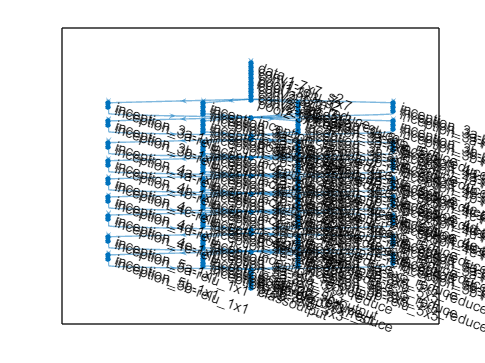

plot(lgraph);

# Create and Train a Deep Learning Model

Script for creating and training a deep learning network with the following properties:

Run this script to create the network layers, import training and validation data, and train the network. The network layers are stored in the workspace variable `lgraph`. The trained network is stored in the workspace variable `net`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 25-Aug-2023 15:00:26

## Load Training Setup Data

Load the data used to set up training. The training setup file contains the parameters for network initialization and the training data. For transfer learning, the network initialization parameters are the parameters of the initial pretrained network.

trainingSetup = load("C:\Users\anand\TrainNetworkProject1\params_2023_08_25__15_00_18.mat");

## Import Data

Import training data.

dsTrain = trainingSetup.dsTrain;

## Set Training Options

Specify options to use when training.

opts = trainingOptions("sgdm",...
    "ExecutionEnvironment","auto",...
    "InitialLearnRate",0.01,...
    "LearnRateSchedule","piecewise",...
    "MaxEpochs",3,...
    "Shuffle","every-epoch",...
    "Plots","training-progress");

## Create Layer Graph

Create the layer graph variable to contain the network layers.

lgraph = layerGraph();

## Add Layer Branches

Add the branches of the network to the layer graph. Each branch is a linear array of layers.

tempLayers = [
    imageInputLayer([224 224 3],"Name","data","Mean",trainingSetup.data.Mean)
    convolution2dLayer([7 7],64,"Name","conv1-7x7_s2","BiasLearnRateFactor",2,"Padding",[3 3 3 3],"Stride",[2 2],"Bias",trainingSetup.conv1_7x7_s2.Bias,"Weights",trainingSetup.conv1_7x7_s2.Weights)
    reluLayer("Name","conv1-relu_7x7")
    maxPooling2dLayer([3 3],"Name","pool1-3x3_s2","Padding",[0 1 0 1],"Stride",[2 2])
    crossChannelNormalizationLayer(5,"Name","pool1-norm1","K",1)
    convolution2dLayer([1 1],64,"Name","conv2-3x3_reduce","BiasLearnRateFactor",2,"Bias",trainingSetup.conv2_3x3_reduce.Bias,"Weights",trainingSetup.conv2_3x3_reduce.Weights)
    reluLayer("Name","conv2-relu_3x3_reduce")
    convolution2dLayer([3 3],192,"Name","conv2-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1],"Bias",trainingSetup.conv2_3x3.Bias,"Weights",trainingSetup.conv2_3x3.Weights)
    reluLayer("Name","conv2-relu_3x3")
    crossChannelNormalizationLayer(5,"Name","conv2-norm2","K",1)
    maxPooling2dLayer([3 3],"Name","pool2-3x3_s2","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],64,"Name","inception_3a-1x1","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_3a_1x1.Bias,"Weights",trainingSetup.inception_3a_1x1.Weights)
    reluLayer("Name","inception_3a-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],96,"Name","inception_3a-3x3_reduce","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_3a_3x3_reduce.Bias,"Weights",trainingSetup.inception_3a_3x3_reduce.Weights)
    reluLayer("Name","inception_3a-relu_3x3_reduce")
    convolution2dLayer([3 3],128,"Name","inception_3a-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1],"Bias",trainingSetup.inception_3a_3x3.Bias,"Weights",trainingSetup.inception_3a_3x3.Weights)
    reluLayer("Name","inception_3a-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],16,"Name","inception_3a-5x5_reduce","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_3a_5x5_reduce.Bias,"Weights",trainingSetup.inception_3a_5x5_reduce.Weights)
    reluLayer("Name","inception_3a-relu_5x5_reduce")
    convolution2dLayer([5 5],32,"Name","inception_3a-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2],"Bias",trainingSetup.inception_3a_5x5.Bias,"Weights",trainingSetup.inception_3a_5x5.Weights)
    reluLayer("Name","inception_3a-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_3a-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],32,"Name","inception_3a-pool_proj","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_3a_pool_proj.Bias,"Weights",trainingSetup.inception_3a_pool_proj.Weights)
    reluLayer("Name","inception_3a-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_3a-output");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_3b-1x1","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_3b_1x1.Bias,"Weights",trainingSetup.inception_3b_1x1.Weights)
    reluLayer("Name","inception_3b-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_3b-3x3_reduce","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_3b_3x3_reduce.Bias,"Weights",trainingSetup.inception_3b_3x3_reduce.Weights)
    reluLayer("Name","inception_3b-relu_3x3_reduce")
    convolution2dLayer([3 3],192,"Name","inception_3b-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1],"Bias",trainingSetup.inception_3b_3x3.Bias,"Weights",trainingSetup.inception_3b_3x3.Weights)
    reluLayer("Name","inception_3b-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_3b-5x5_reduce","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_3b_5x5_reduce.Bias,"Weights",trainingSetup.inception_3b_5x5_reduce.Weights)
    reluLayer("Name","inception_3b-relu_5x5_reduce")
    convolution2dLayer([5 5],96,"Name","inception_3b-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2],"Bias",trainingSetup.inception_3b_5x5.Bias,"Weights",trainingSetup.inception_3b_5x5.Weights)
    reluLayer("Name","inception_3b-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_3b-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_3b-pool_proj","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_3b_pool_proj.Bias,"Weights",trainingSetup.inception_3b_pool_proj.Weights)
    reluLayer("Name","inception_3b-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_3b-output")
    maxPooling2dLayer([3 3],"Name","pool3-3x3_s2","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],192,"Name","inception_4a-1x1","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_4a_1x1.Bias,"Weights",trainingSetup.inception_4a_1x1.Weights)
    reluLayer("Name","inception_4a-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],96,"Name","inception_4a-3x3_reduce","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_4a_3x3_reduce.Bias,"Weights",trainingSetup.inception_4a_3x3_reduce.Weights)
    reluLayer("Name","inception_4a-relu_3x3_reduce")
    convolution2dLayer([3 3],208,"Name","inception_4a-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1],"Bias",trainingSetup.inception_4a_3x3.Bias,"Weights",trainingSetup.inception_4a_3x3.Weights)
    reluLayer("Name","inception_4a-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],16,"Name","inception_4a-5x5_reduce","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_4a_5x5_reduce.Bias,"Weights",trainingSetup.inception_4a_5x5_reduce.Weights)
    reluLayer("Name","inception_4a-relu_5x5_reduce")
    convolution2dLayer([5 5],48,"Name","inception_4a-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2],"Bias",trainingSetup.inception_4a_5x5.Bias,"Weights",trainingSetup.inception_4a_5x5.Weights)
    reluLayer("Name","inception_4a-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4a-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4a-pool_proj","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_4a_pool_proj.Bias,"Weights",trainingSetup.inception_4a_pool_proj.Weights)
    reluLayer("Name","inception_4a-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4a-output");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_4b-1x1","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_4b_1x1.Bias,"Weights",trainingSetup.inception_4b_1x1.Weights)
    reluLayer("Name","inception_4b-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],112,"Name","inception_4b-3x3_reduce","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_4b_3x3_reduce.Bias,"Weights",trainingSetup.inception_4b_3x3_reduce.Weights)
    reluLayer("Name","inception_4b-relu_3x3_reduce")
    convolution2dLayer([3 3],224,"Name","inception_4b-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1],"Bias",trainingSetup.inception_4b_3x3.Bias,"Weights",trainingSetup.inception_4b_3x3.Weights)
    reluLayer("Name","inception_4b-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],24,"Name","inception_4b-5x5_reduce","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_4b_5x5_reduce.Bias,"Weights",trainingSetup.inception_4b_5x5_reduce.Weights)
    reluLayer("Name","inception_4b-relu_5x5_reduce")
    convolution2dLayer([5 5],64,"Name","inception_4b-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2],"Bias",trainingSetup.inception_4b_5x5.Bias,"Weights",trainingSetup.inception_4b_5x5.Weights)
    reluLayer("Name","inception_4b-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4b-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4b-pool_proj","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_4b_pool_proj.Bias,"Weights",trainingSetup.inception_4b_pool_proj.Weights)
    reluLayer("Name","inception_4b-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4b-output");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_4c-1x1","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_4c_1x1.Bias,"Weights",trainingSetup.inception_4c_1x1.Weights)
    reluLayer("Name","inception_4c-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_4c-3x3_reduce","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_4c_3x3_reduce.Bias,"Weights",trainingSetup.inception_4c_3x3_reduce.Weights)
    reluLayer("Name","inception_4c-relu_3x3_reduce")
    convolution2dLayer([3 3],256,"Name","inception_4c-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1],"Bias",trainingSetup.inception_4c_3x3.Bias,"Weights",trainingSetup.inception_4c_3x3.Weights)
    reluLayer("Name","inception_4c-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],24,"Name","inception_4c-5x5_reduce","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_4c_5x5_reduce.Bias,"Weights",trainingSetup.inception_4c_5x5_reduce.Weights)
    reluLayer("Name","inception_4c-relu_5x5_reduce")
    convolution2dLayer([5 5],64,"Name","inception_4c-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2],"Bias",trainingSetup.inception_4c_5x5.Bias,"Weights",trainingSetup.inception_4c_5x5.Weights)
    reluLayer("Name","inception_4c-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4c-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4c-pool_proj","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_4c_pool_proj.Bias,"Weights",trainingSetup.inception_4c_pool_proj.Weights)
    reluLayer("Name","inception_4c-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4c-output");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],112,"Name","inception_4d-1x1","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_4d_1x1.Bias,"Weights",trainingSetup.inception_4d_1x1.Weights)
    reluLayer("Name","inception_4d-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],144,"Name","inception_4d-3x3_reduce","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_4d_3x3_reduce.Bias,"Weights",trainingSetup.inception_4d_3x3_reduce.Weights)
    reluLayer("Name","inception_4d-relu_3x3_reduce")
    convolution2dLayer([3 3],288,"Name","inception_4d-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1],"Bias",trainingSetup.inception_4d_3x3.Bias,"Weights",trainingSetup.inception_4d_3x3.Weights)
    reluLayer("Name","inception_4d-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_4d-5x5_reduce","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_4d_5x5_reduce.Bias,"Weights",trainingSetup.inception_4d_5x5_reduce.Weights)
    reluLayer("Name","inception_4d-relu_5x5_reduce")
    convolution2dLayer([5 5],64,"Name","inception_4d-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2],"Bias",trainingSetup.inception_4d_5x5.Bias,"Weights",trainingSetup.inception_4d_5x5.Weights)
    reluLayer("Name","inception_4d-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4d-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4d-pool_proj","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_4d_pool_proj.Bias,"Weights",trainingSetup.inception_4d_pool_proj.Weights)
    reluLayer("Name","inception_4d-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4d-output");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","inception_4e-1x1","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_4e_1x1.Bias,"Weights",trainingSetup.inception_4e_1x1.Weights)
    reluLayer("Name","inception_4e-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_4e-3x3_reduce","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_4e_3x3_reduce.Bias,"Weights",trainingSetup.inception_4e_3x3_reduce.Weights)
    reluLayer("Name","inception_4e-relu_3x3_reduce")
    convolution2dLayer([3 3],320,"Name","inception_4e-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1],"Bias",trainingSetup.inception_4e_3x3.Bias,"Weights",trainingSetup.inception_4e_3x3.Weights)
    reluLayer("Name","inception_4e-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_4e-5x5_reduce","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_4e_5x5_reduce.Bias,"Weights",trainingSetup.inception_4e_5x5_reduce.Weights)
    reluLayer("Name","inception_4e-relu_5x5_reduce")
    convolution2dLayer([5 5],128,"Name","inception_4e-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2],"Bias",trainingSetup.inception_4e_5x5.Bias,"Weights",trainingSetup.inception_4e_5x5.Weights)
    reluLayer("Name","inception_4e-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4e-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_4e-pool_proj","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_4e_pool_proj.Bias,"Weights",trainingSetup.inception_4e_pool_proj.Weights)
    reluLayer("Name","inception_4e-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_4e-output")
    maxPooling2dLayer([3 3],"Name","pool4-3x3_s2","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","inception_5a-1x1","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_5a_1x1.Bias,"Weights",trainingSetup.inception_5a_1x1.Weights)
    reluLayer("Name","inception_5a-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_5a-3x3_reduce","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_5a_3x3_reduce.Bias,"Weights",trainingSetup.inception_5a_3x3_reduce.Weights)
    reluLayer("Name","inception_5a-relu_3x3_reduce")
    convolution2dLayer([3 3],320,"Name","inception_5a-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1],"Bias",trainingSetup.inception_5a_3x3.Bias,"Weights",trainingSetup.inception_5a_3x3.Weights)
    reluLayer("Name","inception_5a-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_5a-5x5_reduce","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_5a_5x5_reduce.Bias,"Weights",trainingSetup.inception_5a_5x5_reduce.Weights)
    reluLayer("Name","inception_5a-relu_5x5_reduce")
    convolution2dLayer([5 5],128,"Name","inception_5a-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2],"Bias",trainingSetup.inception_5a_5x5.Bias,"Weights",trainingSetup.inception_5a_5x5.Weights)
    reluLayer("Name","inception_5a-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_5a-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_5a-pool_proj","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_5a_pool_proj.Bias,"Weights",trainingSetup.inception_5a_pool_proj.Weights)
    reluLayer("Name","inception_5a-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_5a-output");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],384,"Name","inception_5b-1x1","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_5b_1x1.Bias,"Weights",trainingSetup.inception_5b_1x1.Weights)
    reluLayer("Name","inception_5b-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],192,"Name","inception_5b-3x3_reduce","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_5b_3x3_reduce.Bias,"Weights",trainingSetup.inception_5b_3x3_reduce.Weights)
    reluLayer("Name","inception_5b-relu_3x3_reduce")
    convolution2dLayer([3 3],384,"Name","inception_5b-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1],"Bias",trainingSetup.inception_5b_3x3.Bias,"Weights",trainingSetup.inception_5b_3x3.Weights)
    reluLayer("Name","inception_5b-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],48,"Name","inception_5b-5x5_reduce","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_5b_5x5_reduce.Bias,"Weights",trainingSetup.inception_5b_5x5_reduce.Weights)
    reluLayer("Name","inception_5b-relu_5x5_reduce")
    convolution2dLayer([5 5],128,"Name","inception_5b-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2],"Bias",trainingSetup.inception_5b_5x5.Bias,"Weights",trainingSetup.inception_5b_5x5.Weights)
    reluLayer("Name","inception_5b-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_5b-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_5b-pool_proj","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_5b_pool_proj.Bias,"Weights",trainingSetup.inception_5b_pool_proj.Weights)
    reluLayer("Name","inception_5b-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_5b-output")
    globalAveragePooling2dLayer("Name","pool5-7x7_s1")
    dropoutLayer(0.4,"Name","pool5-drop_7x7_s1")
    fullyConnectedLayer(5,"Name","fc")
    softmaxLayer("Name","prob")
    classificationLayer("Name","classoutput")];
lgraph = addLayers(lgraph,tempLayers);

% clean up helper variable
clear tempLayers;

## Connect Layer Branches

Connect all the branches of the network to create the network graph.

lgraph = connectLayers(lgraph,"pool2-3x3_s2","inception_3a-1x1");
lgraph = connectLayers(lgraph,"pool2-3x3_s2","inception_3a-3x3_reduce");
lgraph = connectLayers(lgraph,"pool2-3x3_s2","inception_3a-5x5_reduce");
lgraph = connectLayers(lgraph,"pool2-3x3_s2","inception_3a-pool");
lgraph = connectLayers(lgraph,"inception_3a-relu_1x1","inception_3a-output/in1");
lgraph = connectLayers(lgraph,"inception_3a-relu_3x3","inception_3a-output/in2");
lgraph = connectLayers(lgraph,"inception_3a-relu_5x5","inception_3a-output/in3");
lgraph = connectLayers(lgraph,"inception_3a-relu_pool_proj","inception_3a-output/in4");
lgraph = connectLayers(lgraph,"inception_3a-output","inception_3b-1x1");
lgraph = connectLayers(lgraph,"inception_3a-output","inception_3b-3x3_reduce");
lgraph = connectLayers(lgraph,"inception_3a-output","inception_3b-5x5_reduce");
lgraph = connectLayers(lgraph,"inception_3a-output","inception_3b-pool");
lgraph = connectLayers(lgraph,"inception_3b-relu_1x1","inception_3b-output/in1");
lgraph = connectLayers(lgraph,"inception_3b-relu_3x3","inception_3b-output/in2");
lgraph = connectLayers(lgraph,"inception_3b-relu_5x5","inception_3b-output/in3");
lgraph = connectLayers(lgraph,"inception_3b-relu_pool_proj","inception_3b-output/in4");
lgraph = connectLayers(lgraph,"pool3-3x3_s2","inception_4a-1x1");
lgraph = connectLayers(lgraph,"pool3-3x3_s2","inception_4a-3x3_reduce");
lgraph = connectLayers(lgraph,"pool3-3x3_s2","inception_4a-5x5_reduce");
lgraph = connectLayers(lgraph,"pool3-3x3_s2","inception_4a-pool");
lgraph = connectLayers(lgraph,"inception_4a-relu_1x1","inception_4a-output/in1");
lgraph = connectLayers(lgraph,"inception_4a-relu_3x3","inception_4a-output/in2");
lgraph = connectLayers(lgraph,"inception_4a-relu_5x5","inception_4a-output/in3");
lgraph = connectLayers(lgraph,"inception_4a-relu_pool_proj","inception_4a-output/in4");
lgraph = connectLayers(lgraph,"inception_4a-output","inception_4b-1x1");
lgraph = connectLayers(lgraph,"inception_4a-output","inception_4b-3x3_reduce");
lgraph = connectLayers(lgraph,"inception_4a-output","inception_4b-5x5_reduce");
lgraph = connectLayers(lgraph,"inception_4a-output","inception_4b-pool");
lgraph = connectLayers(lgraph,"inception_4b-relu_1x1","inception_4b-output/in1");
lgraph = connectLayers(lgraph,"inception_4b-relu_3x3","inception_4b-output/in2");
lgraph = connectLayers(lgraph,"inception_4b-relu_5x5","inception_4b-output/in3");
lgraph = connectLayers(lgraph,"inception_4b-relu_pool_proj","inception_4b-output/in4");
lgraph = connectLayers(lgraph,"inception_4b-output","inception_4c-1x1");
lgraph = connectLayers(lgraph,"inception_4b-output","inception_4c-3x3_reduce");
lgraph = connectLayers(lgraph,"inception_4b-output","inception_4c-5x5_reduce");
lgraph = connectLayers(lgraph,"inception_4b-output","inception_4c-pool");
lgraph = connectLayers(lgraph,"inception_4c-relu_1x1","inception_4c-output/in1");
lgraph = connectLayers(lgraph,"inception_4c-relu_3x3","inception_4c-output/in2");
lgraph = connectLayers(lgraph,"inception_4c-relu_5x5","inception_4c-output/in3");
lgraph = connectLayers(lgraph,"inception_4c-relu_pool_proj","inception_4c-output/in4");
lgraph = connectLayers(lgraph,"inception_4c-output","inception_4d-1x1");
lgraph = connectLayers(lgraph,"inception_4c-output","inception_4d-3x3_reduce");
lgraph = connectLayers(lgraph,"inception_4c-output","inception_4d-5x5_reduce");
lgraph = connectLayers(lgraph,"inception_4c-output","inception_4d-pool");
lgraph = connectLayers(lgraph,"inception_4d-relu_1x1","inception_4d-output/in1");
lgraph = connectLayers(lgraph,"inception_4d-relu_3x3","inception_4d-output/in2");
lgraph = connectLayers(lgraph,"inception_4d-relu_5x5","inception_4d-output/in3");
lgraph = connectLayers(lgraph,"inception_4d-relu_pool_proj","inception_4d-output/in4");
lgraph = connectLayers(lgraph,"inception_4d-output","inception_4e-1x1");
lgraph = connectLayers(lgraph,"inception_4d-output","inception_4e-3x3_reduce");
lgraph = connectLayers(lgraph,"inception_4d-output","inception_4e-5x5_reduce");
lgraph = connectLayers(lgraph,"inception_4d-output","inception_4e-pool");
lgraph = connectLayers(lgraph,"inception_4e-relu_1x1","inception_4e-output/in1");
lgraph = connectLayers(lgraph,"inception_4e-relu_3x3","inception_4e-output/in2");
lgraph = connectLayers(lgraph,"inception_4e-relu_5x5","inception_4e-output/in3");
lgraph = connectLayers(lgraph,"inception_4e-relu_pool_proj","inception_4e-output/in4");
lgraph = connectLayers(lgraph,"pool4-3x3_s2","inception_5a-1x1");
lgraph = connectLayers(lgraph,"pool4-3x3_s2","inception_5a-3x3_reduce");
lgraph = connectLayers(lgraph,"pool4-3x3_s2","inception_5a-5x5_reduce");
lgraph = connectLayers(lgraph,"pool4-3x3_s2","inception_5a-pool");
lgraph = connectLayers(lgraph,"inception_5a-relu_1x1","inception_5a-output/in1");
lgraph = connectLayers(lgraph,"inception_5a-relu_3x3","inception_5a-output/in2");
lgraph = connectLayers(lgraph,"inception_5a-relu_5x5","inception_5a-output/in3");
lgraph = connectLayers(lgraph,"inception_5a-relu_pool_proj","inception_5a-output/in4");
lgraph = connectLayers(lgraph,"inception_5a-output","inception_5b-1x1");
lgraph = connectLayers(lgraph,"inception_5a-output","inception_5b-3x3_reduce");
lgraph = connectLayers(lgraph,"inception_5a-output","inception_5b-5x5_reduce");
lgraph = connectLayers(lgraph,"inception_5a-output","inception_5b-pool");
lgraph = connectLayers(lgraph,"inception_5b-relu_1x1","inception_5b-output/in1");
lgraph = connectLayers(lgraph,"inception_5b-relu_3x3","inception_5b-output/in2");
lgraph = connectLayers(lgraph,"inception_5b-relu_5x5","inception_5b-output/in3");
lgraph = connectLayers(lgraph,"inception_5b-relu_pool_proj","inception_5b-output/in4");

## Train Network

Train the network using the specified options and training data.

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:36 |       22.66% |       2.6911 |          0.0100 |
|       2 |          20 |       00:11:10 |       94.53% |       0.1533 |          0.0100 |
|========================================================================================|
Training finished: Stopped manually.


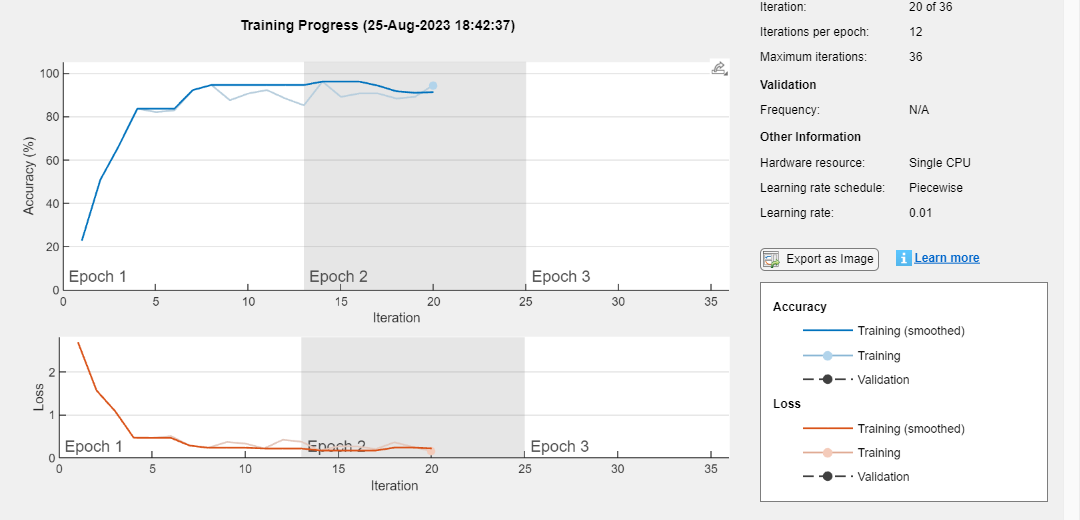

Unable to resolve the name 'trainInfoStruct_2.BaseLearnRate'.

[net, traininfo] = trainNetwork(dsTrain,lgraph,opts);


sherlock = "C:\Users\anand\OneDrive\Desktop\sherlock.jpg"

sherlock = "C:\Users\anand\OneDrive\Desktop\sherlock.jpg"


img = imread(sherlock);
inputSize = trainedNetwork_1.Layers(1).InputSize;
img = imresize(img,inputSize(1:2));

net = trainedNetwork_1

net =   DAGNetwork with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'classoutput'}


classes = categories(trainedNetwork_1.Layers(end).Classes)

classes = 5×1 cell array
    {'baboon'   }
    {'candle'   }
    {'cats'     }
    {'dogs'     }
    {'hourglass'}


trainInfoStruct_1 = struct with fields:
              TrainingLoss: [2.8305 1.7032 0.8332 0.6497 0.5491 0.2485 0.3776 0.2731 0.2461 0.2721 0.1865 0.1638 0.0779 0.1415]
          TrainingAccuracy: [25 45.3125 67.1875 78.9062 77.3438 92.9688 86.7188 88.2812 91.4062 89.8438 92.1875 92.9688 98.4375 96.8750]
             BaseLearnRate: [0.0100 0.0100 0.0100 0.0100 0.0100 0.0100 0.0100 0.0100 0.0100 0.0100 0.0100 0.0100 0.0100 0.0100]
    OutputNetworkIteration: 14


trainInfoStruct_1 = struct with fields:
              TrainingLoss: [2.8305 1.7032 0.8332 0.6497 0.5491 0.2485 0.3776 0.2731 0.2461 0.2721 0.1865 0.1638 0.0779 0.1415]
          TrainingAccuracy: [25 45.3125 67.1875 78.9062 77.3438 92.9688 86.7188 88.2812 91.4062 89.8438 92.1875 92.9688 98.4375 96.8750]
             BaseLearnRate: [0.0100 0.0100 0.0100 0.0100 0.0100 0.0100 0.0100 0.0100 0.0100 0.0100 0.0100 0.0100 0.0100 0.0100]
    OutputNetworkIteration: 14


Actual = dataTest.Labels;
predictions  = classify(trainedNetwork_1,Testset_1)

predictions = 660×1 categorical array
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 


numCorrect = nnz(predictions == Actual)

numCorrect = 635


fracCorrect = numCorrect/numel(predictions)

fracCorrect = 0.9424

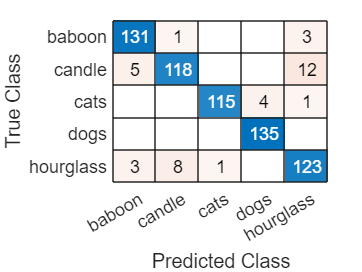

confusionchart(Actual,predictions)

% Assuming C is your confusion matrix
C = confusionmat(Actual,predictions);

% Total number of classifications
total = sum(sum(C));

% True Positive
TP = diag(C);

% False Positive
FP = sum(C, 1)' - TP;

% False Negative
FN = sum(C, 2) - TP;

% True Negative
TN = total - FP - FN - TP;

% Accuracy
accuracy = sum(TP) / total;

% Precision, Recall, and F1-score for each class
precision = TP ./ (TP + FP);
recall = TP ./ (TP + FN);
f1_score = 2 * (precision .* recall) ./ (precision + recall);

% Display the results
disp(['Accuracy: ', num2str(accuracy)]);

Accuracy: 0.94242


disp('Precision:'); disp(precision);

Precision:
    0.9424
    0.9291
    0.9914
    0.9712
    0.8849



disp('Recall:'); disp(recall);

Recall:
    0.9704
    0.8741
    0.9583
    1.0000
    0.9111



F1-Score:
    0.9562
    0.9008
    0.9746
    0.9854
    0.8978



label = categorical
     dogs 


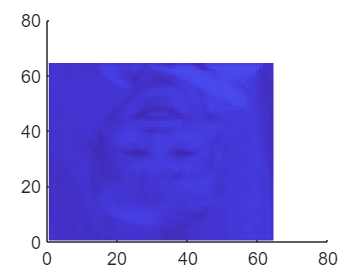

Error using gradCAM
Expected input to be one of these types:

double, single, uint8, uint16, uint32, uint64, int8, int16, int32, int64, double

Instead its type was matlab.graphics.primitive.Image.

image = 640×960×3 uint8 array
image(:,:,1) =

    90    87    85    83    80    77    73    69    65    61    54    49    44    41    37    35    34    31    27    24    22    20    19    17    14    11     9     7     7     6     4     2     2     2     2     2     2     2     2     2     2     2     2     3     3     4     4     4     1     1     1     2     2     3     3     3     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     4     5    10    13    18    20    24    29    35    37    41    43    48    50    57    58    61    63    67    68    69    70    71    71    72    73    73    74    74    74    72    72    72    72    72    72    72    72    72    72    72    73    73    74    74    74    75    75    75    75    75    75    75    75    74    74    74    75    75    76    76    76    76    76    76    76    76    76    76    76    76    76    76    76    76    76    76

Error using DAGNetwork/classify
Incorrect input size. The input images must have a size of [224 224 3].

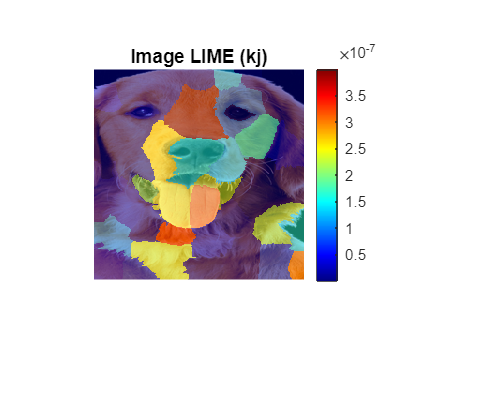

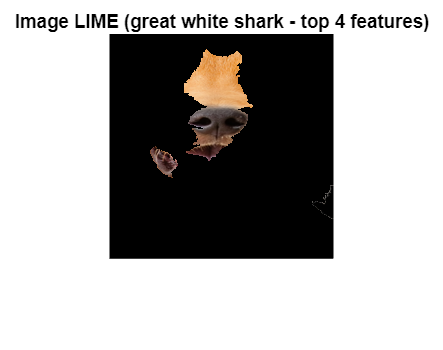

disp('F1-Score:'); disp(f1_score);